# Parameters

clear
mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth);

k = 200

k = 200

%periodo = 3.7837



## Unstable Manifold L1

X0 = [0.803317447531649	0 0 0.333418772378925]

X0 =     0.8033         0         0    0.3334


C1 = jacobiConstant([0.803317447531649	0],[0 0.333418772378925],mu)

C1 = 3.0946

STM = reshape(eye(4),16,[])';
Xunstable = [X0 STM]';
epsilon=1e-4;
periodoUnstable = 3.20588680682668;
X_mainfold_unstable = calculateUnStableMainfold(periodoUnstable,Xunstable,mu,k,epsilon,false);

## stable manifold L2

X0 = [1.19878035065113 0 0 -0.308568876252894];
C1 = jacobiConstant([1.19878035065113 0],[0 -0.308568876252894],mu)

C1 = 3.0946

STM = reshape(eye(4),16,[])';
Xstable = [X0 STM]';
periodoStable = 3.63720278598352;
X_mainfold_stable = calculateStableMainfold(periodoUnstable,Xstable,mu,k,epsilon,-1,false);

## Verificar orbitas

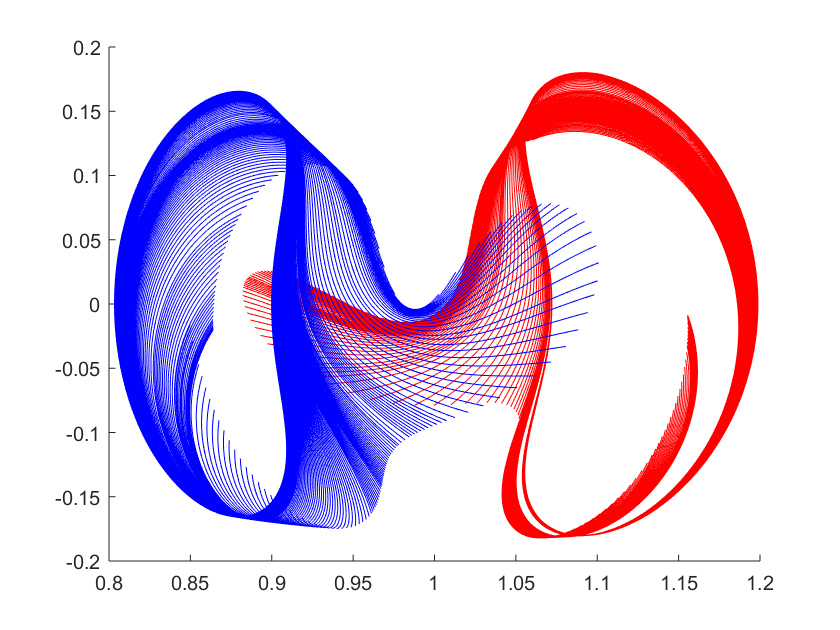

hold on
plotStableMainfold(X_mainfold_stable,periodoStable,k,mu,'r')

plotUnStableMainfold(X_mainfold_unstable,periodoUnstable,k,mu,'b')
hold off

## Calculate Poincare map

ans =        70729           2


ans =      1     2


ans =        54824           2


ans =      1     2


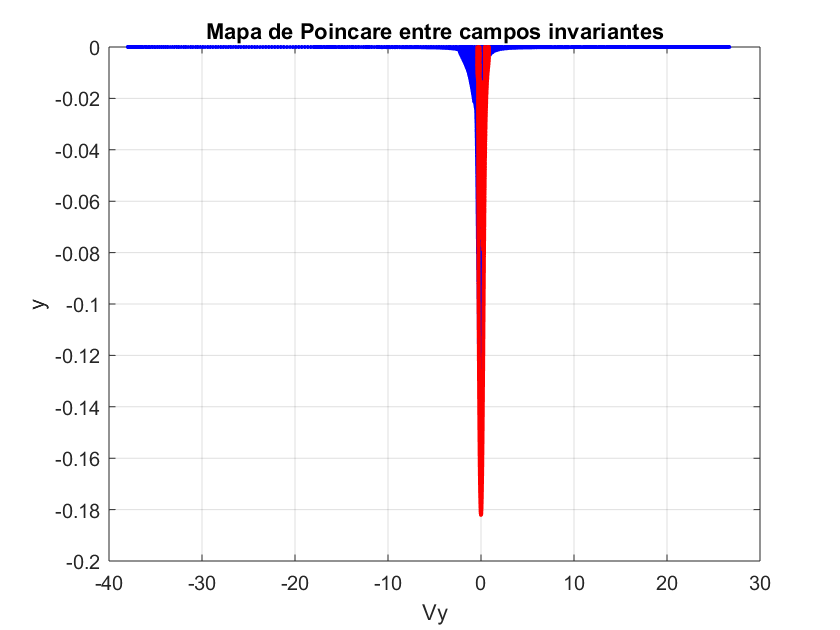


[U2,U3] = callPoincareMap(X_mainfold_unstable,X_mainfold_stable,mu,k,C1,periodoStable,periodoStable);